# Calibration ToF

## Import data

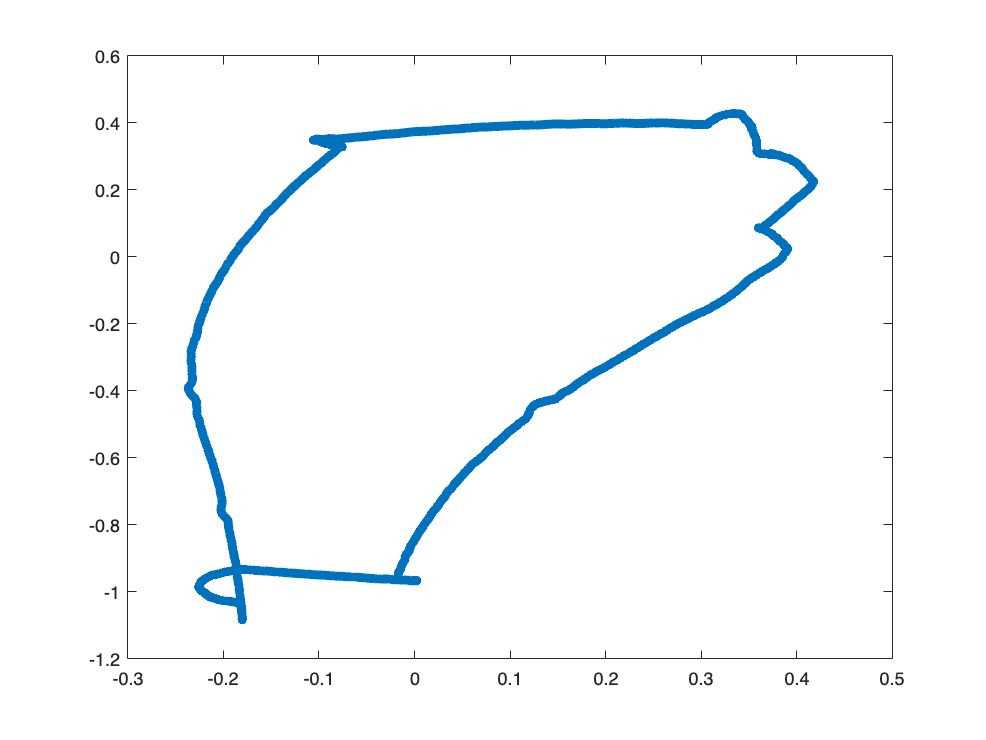

clc; clear; close all;

line = load("../trainingData/task2_2.mat");
GT_position = squeeze(line.out.GT_position.signals.values);
GT_rotation = squeeze(line.out.GT_rotation.signals.values);
GT_time = squeeze(line.out.GT_position.time);
ToF1_raw = squeeze(line.out.Sensor_ToF1.signals.values)';
ToF2_raw = squeeze(line.out.Sensor_ToF2.signals.values)';
ToF3_raw = squeeze(line.out.Sensor_ToF3.signals.values)';
ToF_time = squeeze(line.out.Sensor_ToF1.time)';

figure;
plot(GT_position(:,1), GT_position(:,2), 'LineWidth', 5)


% Magnitometer Data
Mraw = squeeze(line.out.Sensor_MAG.signals.values)';
M_time = squeeze(line.out.Sensor_MAG.time)';
Mx   = Mraw(:,2);
My   = Mraw(:,3);
% Combine for 2D
XY_raw = [Mx, My];

## Magnitometer check

#### Apply

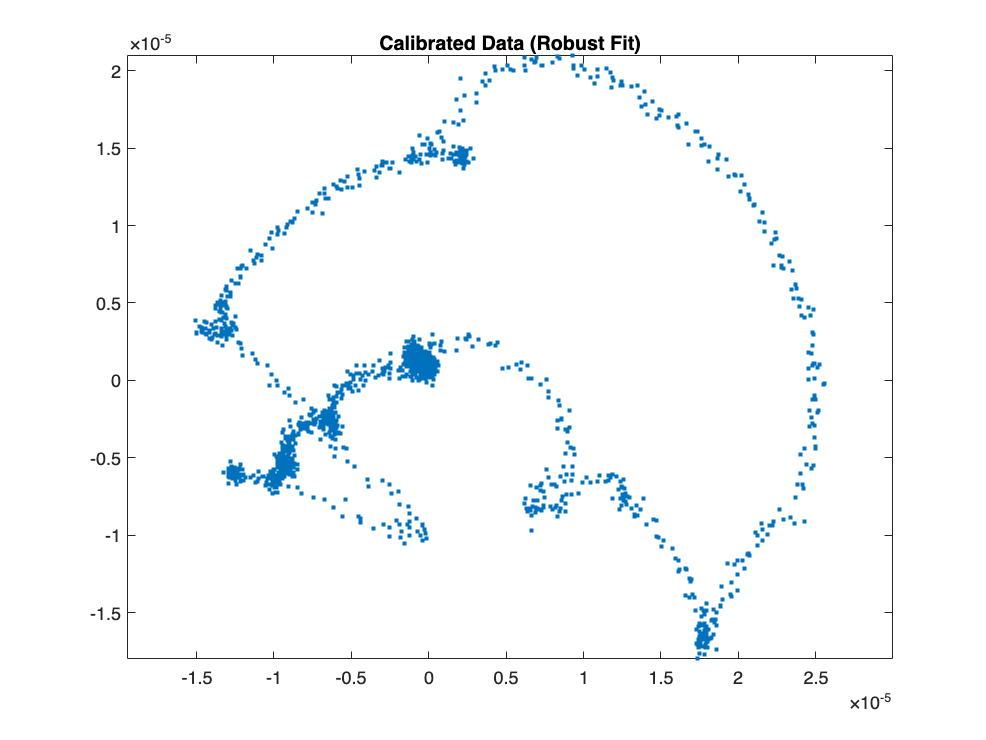

calParams = load("../MAG_calParams.mat");
[calMag, yaw_mag]= applyMagnetometerCalibration2D(XY_raw, calParams.calParams);

figure;
plot(calMag(:,1), calMag(:,2), '.');
title('Calibrated Data (Robust Fit)'); 
axis equal;

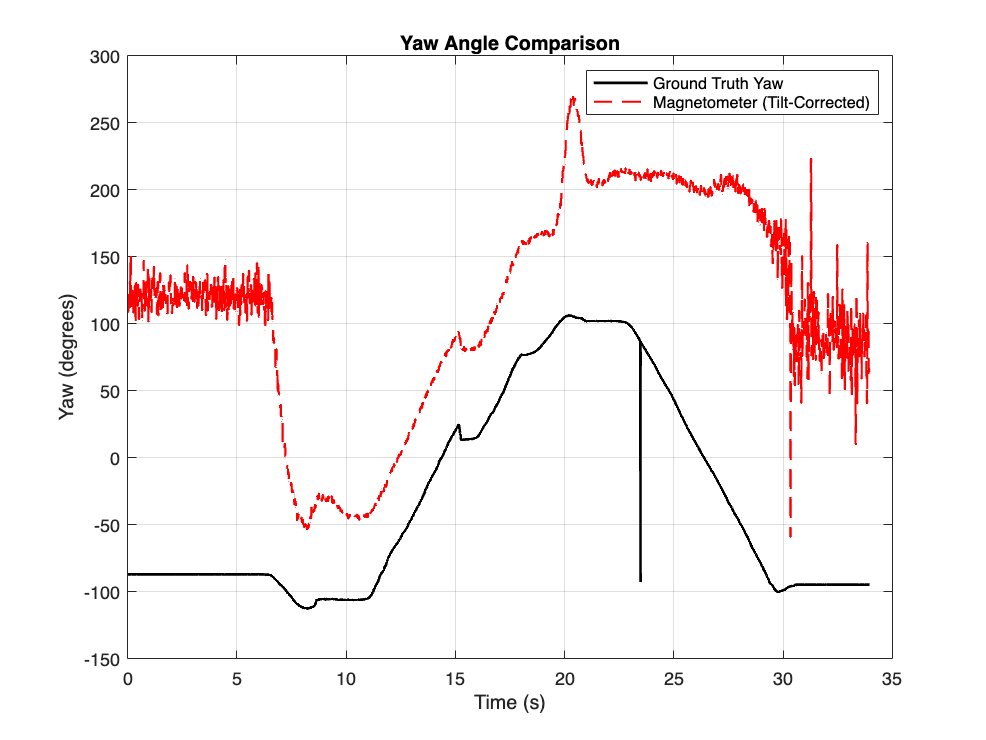


yaw_gt = quat2eul(GT_rotation, 'ZXY');  % [yaw, pitch, roll]
yaw_gt = yaw_gt(:,1);                   % Take yaw only (in radians)
yaw_gt = unwrap(yaw_gt);    % Unwrap to prevent jumps at ±π


figure;
plot(GT_time, rad2deg(yaw_gt), 'k', 'LineWidth', 1.5); hold on;
plot(M_time, rad2deg(yaw_mag), 'r--', 'LineWidth', 1.2);
xlabel('Time (s)'); ylabel('Yaw (degrees)');
legend('Ground Truth Yaw', 'Magnetometer (Tilt-Corrected)');
title('Yaw Angle Comparison');
grid on;

It seems like there are significant outliers after 60 Seconds, therefore, only first 60 seconds will be taken for calibration.

% % Logical index for first 60 seconds
% gt_mask = GT_time <= 60;
% tof_mask = ToF_time <= 60;
% 
% % Apply the mask
% GT_time = GT_time(gt_mask);
% GT_position = GT_position(gt_mask, :);  % if GT_position is Nx2 or Nx3
% 
% ToF_time = ToF_time(tof_mask);
% ToF1_raw = ToF1_raw(1,:);
% ToF2_raw = ToF2_raw(1,:);
% ToF3_raw = ToF3_raw(1,:);
% ToF1_raw = ToF1_raw(tof_mask);
% ToF2_raw = ToF2_raw(tof_mask);
% ToF3_raw = ToF3_raw(tof_mask);
% 
% figure;
% plot(GT_position(:,1), GT_position(:,2), 'LineWidth', 5)

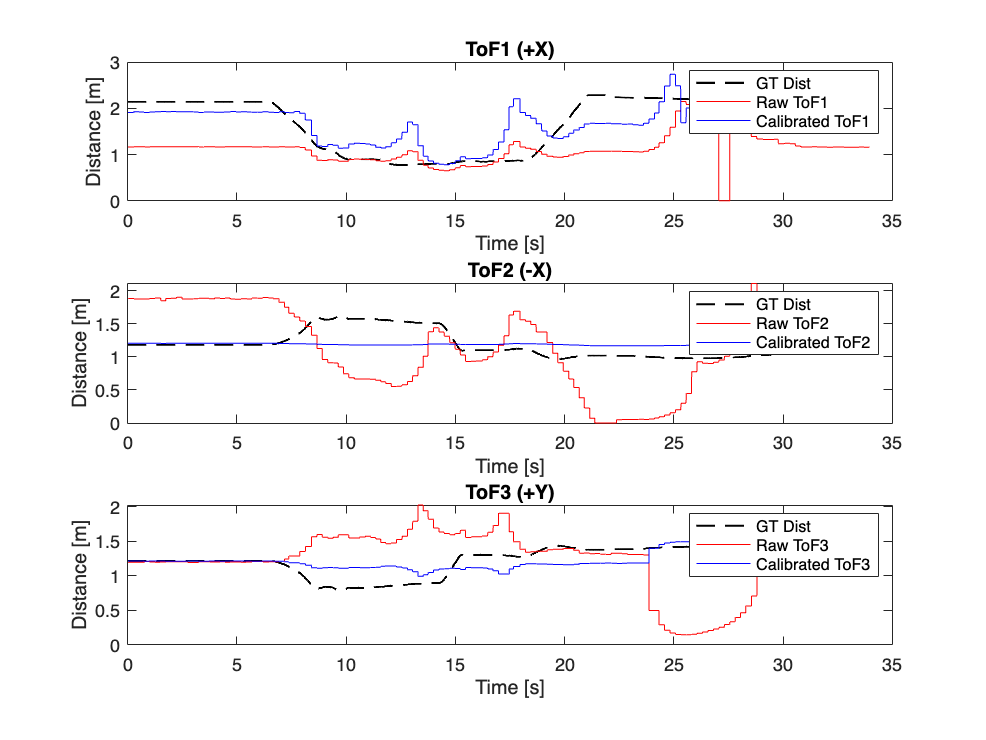

ToF1_raw = ToF1_raw(1,:);
ToF2_raw = ToF2_raw(1,:);
ToF3_raw = ToF3_raw(1,:);
x_wall_right = 1.2;  % wall in +x direction (right)
x_wall_left  = -1.2;  % wall in -x direction (left)
y_wall_front  = 1.2;  % wall in +y direction
y_wall_back  = -1.2;  % wall in -y direction

% Calculate expected true distances for each ToF
GT_x = GT_position(:,1);
GT_y = GT_position(:,2);

expected_ToF1 = abs(y_wall_front - GT_y);  % ToF1 faces forward (+y)
expected_ToF2 = abs(GT_x - x_wall_left);   % ToF2 faces left (-x)
expected_ToF3 = abs(x_wall_right - GT_x);   % ToF3 faces right (+x)

%% Calibrate using linear regression
% You can change the degree of fit for better accuracy

% Linear calibration
p1 = polyfit(ToF1_raw, expected_ToF1, 3);

%Bias only calibration, as the data is not varied enough
p2 = polyfit(ToF2_raw, expected_ToF2, 1);
p3 = polyfit(ToF3_raw, expected_ToF3, 1);

% Apply calibration
ToF1_cal = polyval(p1, ToF1_raw);
ToF2_cal = polyval(p2, ToF2_raw);
ToF3_cal = polyval(p3, ToF3_raw);

%% Plot and compare
figure;
subplot(3,1,1);
plot(ToF_time, expected_ToF1, 'k--', 'LineWidth', 1.2); hold on;
plot(ToF_time, ToF1_raw, 'r'); 
plot(ToF_time, ToF1_cal, 'b');
legend('GT Dist', 'Raw ToF1', 'Calibrated ToF1');
xlabel('Time [s]'); ylabel('Distance [m]'); title('ToF1 (+X)');

subplot(3,1,2);
plot(ToF_time, expected_ToF2, 'k--', 'LineWidth', 1.2); hold on;
plot(ToF_time, ToF2_raw, 'r'); 
plot(ToF_time, ToF2_cal, 'b');
legend('GT Dist', 'Raw ToF2', 'Calibrated ToF2');
xlabel('Time [s]'); ylabel('Distance [m]'); title('ToF2 (-X)');

subplot(3,1,3);
plot(ToF_time, expected_ToF3, 'k--', 'LineWidth', 1.2); hold on;
plot(ToF_time, ToF3_raw, 'r'); 
plot(ToF_time, ToF3_cal, 'b');
legend('GT Dist', 'Raw ToF3', 'Calibrated ToF3');
xlabel('Time [s]'); ylabel('Distance [m]'); title('ToF3 (+Y)');

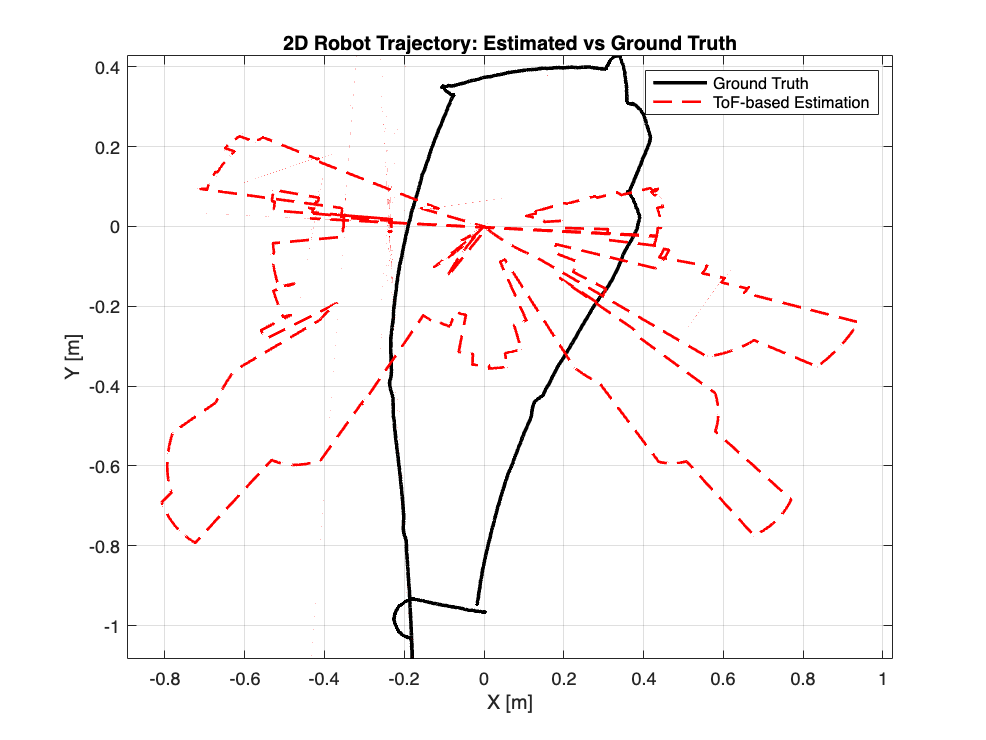

% Extract yaw from quaternion
yaw_gt = quat2eul(GT_rotation, 'ZXY');  % Nx3
yaw = yaw_gt(:,1);  % Just the yaw component
yaw = unwrap(yaw);  % Remove ±pi jumps
ToF_cal = [ToF2_cal; ToF1_cal; ToF3_cal]';

function pos_est_all = estimatePositionFromToFs(tof_distances, yaws, room_halfsize)
% Estimate robot position from 3 ToF sensors, heading, and room walls over time
% Inputs:
%   tof_distances: Nx3 matrix of ToF distances (ToF1, ToF2, ToF3)
%   yaws: Nx1 vector of heading angles in radians
%   room_halfsize: scalar (e.g., 1.2 for 2.4m room centered at (0,0))
% Output:
%   pos_est_all: Nx2 matrix of estimated [x, y] positions

N = size(tof_distances, 1);
pos_est_all = NaN(N, 2);

% Sensor directions in robot frame
dirs_robot = [ 0,  1;  % ToF1 (forward)
              -1,  0;  % ToF2 (left)
               1,  0]; % ToF3 (right)

% Define room walls (cell array to allow mixing numbers and strings)
walls = {
    -room_halfsize, NaN, 'x';  % Left
     room_halfsize, NaN, 'x';  % Right
     NaN,  room_halfsize, 'y'; % Front
     NaN, -room_halfsize, 'y'; % Back
};

for i = 1:N
    distances = tof_distances(i, :);
    yaw = yaws(i);

    % Skip invalid row (e.g., NaNs or zeros)
    if any(isnan(distances)) || all(distances == 0)
        continue;
    end

    % Rotate sensor directions to world frame
    R = [cos(yaw-pi/2), -sin(yaw-pi/2);
         sin(yaw-pi/2),  cos(yaw-pi/2)];
    dirs_world = (R * dirs_robot')';  % 3x2

    estimates = [];

    for j = 1:3
        dir_w = dirs_world(j, :);
        d = distances(j);

        for w = 1:4
            axis = walls{w,3};
            if axis == 'x'
                x_wall = walls{w,1};
                if abs(dir_w(1)) > 1e-3
                    t = x_wall / dir_w(1);
                    if t < 0 || t > d
                        continue;
                    end
                    y_hit = t * dir_w(2);
                    hit = [x_wall, y_hit];
                    pos = hit - d * dir_w;
                    estimates = [estimates; pos];
                end
            else  % axis == 'y'
                y_wall = walls{w,2};
                if abs(dir_w(2)) > 1e-3
                    t = y_wall / dir_w(2);
                    if t < 0 || t > d
                        continue;
                    end
                    x_hit = t * dir_w(1);
                    hit = [x_hit, y_wall];
                    pos = hit - d * dir_w;
                    estimates = [estimates; pos];
                end
            end
        end
    end

    if ~isempty(estimates)
        pos_est_all(i, :) = mean(estimates, 1);  % average of valid ones
    end
end
end

pos = estimatePositionFromToFs(ToF_cal, yaw', 1.2);

% Estimate (Nx2) already available as `positions`
valid_idx = ~any(isnan(pos), 2);  % filter out NaNs if any

figure;
plot(GT_x, GT_y, 'k-', 'LineWidth', 2); hold on;
plot(pos(valid_idx,1), pos(valid_idx,2), 'r--', 'LineWidth', 1.5);
xlabel('X [m]'); ylabel('Y [m]');
legend('Ground Truth', 'ToF-based Estimation');
title('2D Robot Trajectory: Estimated vs Ground Truth');
axis equal; grid on;